# CBF for Industrial Manipulator(PUMA560)

% 2024-05-10
% Reference: F. Ferraguti et al., “Safety and Efficiency in Robotics: The Control Barrier Functions Approach,” IEEE Robot. Automat. Mag., vol. 29, no. 3, pp. 139–151, Sep. 2022, doi: 10.1109/MRA.2022.3174699.

clc
clear
close all

## Model parameters and initial conditions

u_des = [1 0 0 0 0 0]; % Desired q
gamma = 100;
Tf = 3; % Duration
Ts = 0.001; % Sample time
p_obs = [0 0.4 1]; % Position of the obstacle
R = 0.1; % Radious of the obstacle
R_w = 0.1; % Radious of the wrist of robot


## $\gamma$=1, 2, 10

gamma_data = [1 2 10];
num_gamma = length(gamma_data);
t_size = length(0:Ts:Tf) + 1;

px = zeros(num_gamma, t_size);
py = zeros(num_gamma, t_size);
pz = zeros(num_gamma, t_size);
hx = zeros(num_gamma, t_size);
u_act  = zeros(num_gamma, t_size, 6);
q = zeros(num_gamma, t_size, 6);

for i = 1:num_gamma
    gamma = gamma_data(i);

    % Load robot
    robot = loadrobot('puma560', DataFormat="column");
    config = homeConfiguration(robot);
    
    transform = getTransform(robot, config, "link6");
    InitPos = transform(1:3,4);
    
    % Simulink model
    mdl = 'CBF_for_Manipulator';
    open_system(mdl)
    
    out = sim(mdl);
    
    
    % Save data
    logData = out.logsout;
    
    for ct = 1:length(out.tout)
        px(i, ct) = logData{2}.Values.Data(ct, 4);
        py(i, ct) = logData{2}.Values.Data(ct, 5);
        pz(i, ct) = logData{2}.Values.Data(ct, 6);
        hx(i, ct) = logData{4}.Values.Data(ct);
        q(i, ct, :) = logData{3}.Values.Data(ct,:);
        if ct < t_size
            u_act(i, ct, :) = logData{1}.Values.Data(ct, :);
        end
    end

end

## Plot trajectories of the wrist

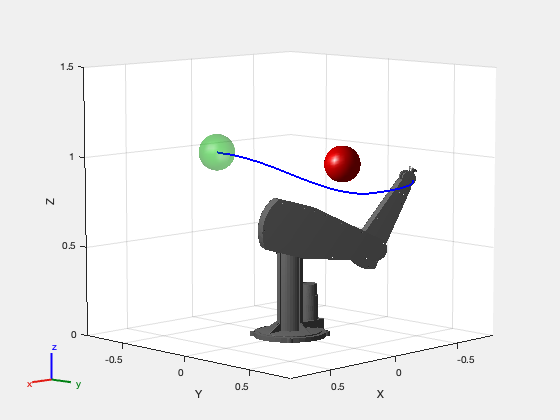

figure(1)
axes = show(robot, config, "Frames","off");
axis([-0.8 0.8 -0.8 0.8 0 1.5]);

% Draw obstacle
[X, Y, Z] = sphere(20);
X = R*X + p_obs(1);
Y = R*Y + p_obs(2);
Z = R*Z + p_obs(3);

s = patch(surf2patch(X, Y, Z));
s.FaceColor = 'red'; 
s.FaceLighting = 'gouraud'; %각 면 간에 조명이 달라지게 해서 곡면으로 보임
s.EdgeAlpha = 0; % 테두리가 없음

% Draw safety volume of the wrist
[X, Y, Z] = sphere(20);
X = R_w*X + InitPos(1);
Y = R_w*Y + InitPos(2);
Z = R_w*Z + InitPos(3);

s = patch(surf2patch(X, Y, Z));
s.FaceColor = 'green'; 
s.FaceLighting = 'gouraud'; %각 면 간에 조명이 달라지게 해서 곡면으로 보임
s.FaceAlpha = 0.3;
s.EdgeAlpha = 0; % 테두리가 없음

figure(1)
hold on
plot3(px(1,:), py(1,:), pz(1,:), 'LineWidth', 2, 'Color','b');
for i = 2:50:length(out.tout)
    show(robot, reshape(q(1,i,:), [6, 1]), 'Frames', 'off', 'PreservePlot',false);
    % pause(out.tout(i) - out.tout(i-1))
    drawnow
end

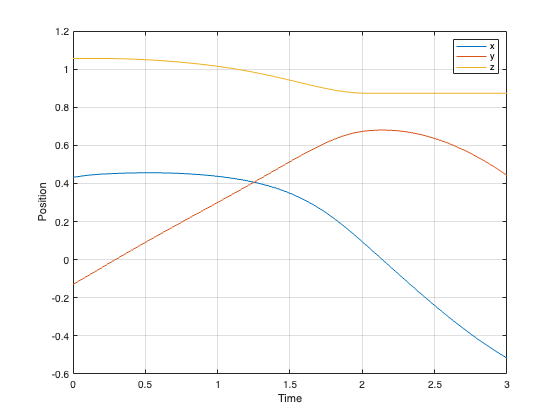


% Plot
figure('Name','Position of the wirst');
plot(out.tout, px(1,:), out.tout, py(1,:),out.tout, pz(1,:)), grid;
xlabel('Time');
ylabel('Position');
legend('x', 'y', 'z');

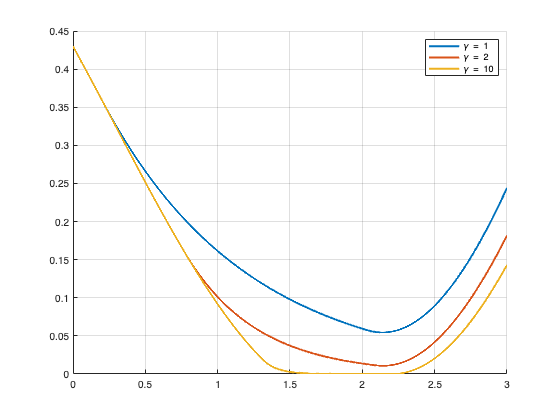


figure('Name','The values of CBF');
for i = 1:num_gamma
    hold on
    plot(out.tout, hx(i, :), 'LineWidth', 2);
end
legend('\gamma = 1', '\gamma = 2', '\gamma = 10')
hold off
grid;

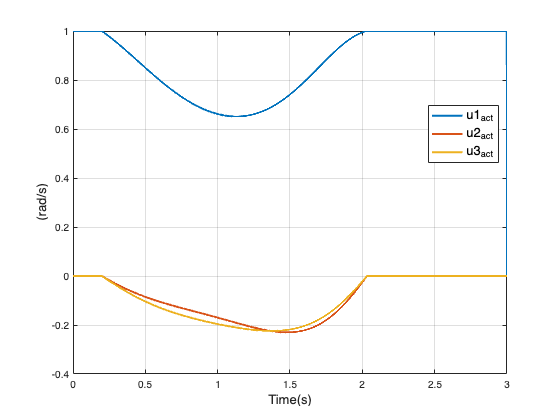


figure('Name','The actuated velocities of the six joints of the manipulator');
u_act = reshape(u_act(1, :, 1:3), [], 3);
plot(out.tout, u_act, 'LineWidth', 2); grid;
xlabel('Time(s)', 'FontSize', 13);
ylabel('(rad/s)', 'FontSize', 13);
legend('u1_{act}', 'u2_{act}', 'u3_{act}', 'Location','best', 'FontSize', 13);